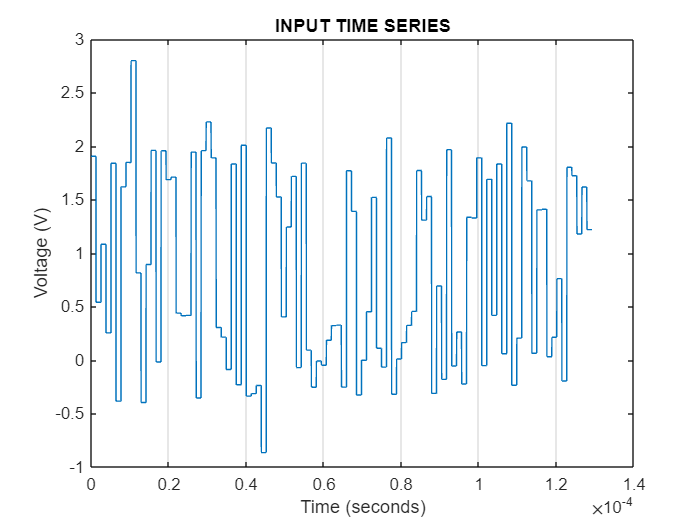

clearvars;
close all;

standard_deviation = 0.294;
dim = 100;

%% GENERATE
 
mdl = 'MZexample';
handle = load_system(mdl);

ws = get_param(mdl, 'ModelWorkspace');
st = ws.getVariable('sample_time');
bs = ws.getVariable('bit_sample');
Vp = ws.getVariable('V_pi');
[noise_ts, unalt_ts] = generate_input(st, bs, dim, Vp, ...
    standard_deviation);
noise_ts.plot
ylabel('Voltage (V)')
set(gca,"XGrid","on","YGrid","off")

title("INPUT TIME SERIES")


%% SET MODEL

 

in = Simulink.SimulationInput(mdl);
bit_time    = st*bs;
total_time  = dim*bit_time;
in = in.setVariable("noise_ts", noise_ts, "Workspace",mdl);
in = in.setModelParameter(StartTime="0", StopTime=string(total_time));
in.applyToModel;

